%% UR5 Trajectory Simulation
% This example shows how to generate and simulate interpolated joint trajectories 
% to move from an initial to a desired end-effector pose. The timing of the trajectories 
% is based on an approximate desired end of arm tool (EOAT) speed. This is based 
% off of a modified example made by Mathworks:
% 
% https://www.mathworks.com/help/robotics/ug/plan-and-execute-trajectory-kinova-gen3.html
%% Creating the Robot
% Load the Universal Robots UR5 rigid body tree (RBT) robot model.

robot = loadrobot('universalUR5','DataFormat','row','Gravity',[0 0 -9.81]);
endEffector = "tool0";
%% Inverse Kinematics
% Set current robot joint configuration.

% Compute initial robot joint configuration using inverse kinematics and
% set it as the robot's current configuration

% The initial task coordinates need to be expressed as a homogenous
% transformation matrix. We can do this by converting and combining a
% transformation vector for the end effector's position, and an axis-angle
% representation for its orientation.

taskInit = trvec2tform([[0 0 0.35]])*axang2tform([0 1 0 pi]);

% MATLAB's built-in inverse kinematics solver uses an inverseKinematics
% object that considers the particular structure of the robot being
% analyzed.

ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

% In order to calculate the inverse kinematics for a particular end
% effector pose, we need to provide the ik object with a 'weights'
% parameter telling it how much we care about the accuracy for each
% of the pose's components. Since MATLAB is performing a numerical
% calculation, we also need to provide it with an initial guess for the
% robot's configuration. Set this initial guess as the robot's
% homeConfiguration with robot.homeConfiguration.

%currentRobotJConfig = ik(endEffector, taskInit, weights, INSERT GUESS HERE);
currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);
currentRobotJConfig = wrapToPi(currentRobotJConfig)

currentRobotJConfig =    -0.7854   -0.8011   -2.2436    1.4739   -1.5797    0.7854


%% 
% *Question:* _Using the above code for the inverse kinematics, can you find 
% the joint coordinates needed to position the end effector at a position of [0 
% 0.3 0.1] with a ZYX Euler representation of [0 0 0]?_
A = trvec2tform([0,0.3,0.1])*eul2tform([pi/2,0,0]);
Ans = ik(endEffector, A, weights, robot.homeConfiguration);
Ans = wrapToPi(Ans)

Ans =     1.1984    1.5370   -2.6583   -0.4494    1.5708   -1.1984


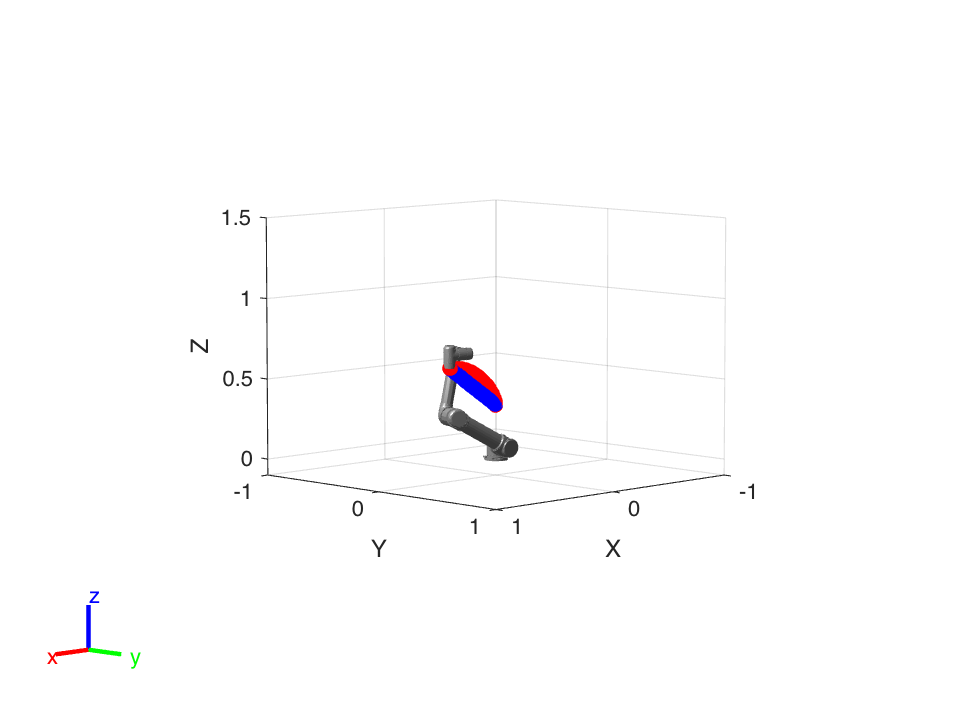

% 
% Get number of joints.

numJoints = numel(currentRobotJConfig);
%% 
% Specify the trajectory time step and approximate desired tool speed.

timeStep = 0.1; % seconds
toolSpeed = 0.05; % m/s
%% 
% Set the initial and final end-effector pose.

jointInit = currentRobotJConfig;
taskInit = getTransform(robot,jointInit,endEffector);
% Set the desired end-effector pose in the same way as we defined the
% initial pose
taskFinal = trvec2tform([0.4,0,0.6])*axang2tform([0 1 0 pi]);
%% Control Task-Space Motion
% Create a joint space motion model for PD control on the joints. The |taskSpaceMotionModel| 
% object models the motion of a rigid body tree model under task-space proportional-derivative 
% control.

tsMotionModel = taskSpaceMotionModel('RigidBodyTree',robot,'EndEffectorName','tool0');
%% 
% Set the proportional and derivative gains on orientation to zero, so that 
% controlled behavior just follows the reference positions:

tsMotionModel.Kp(1:3,1:3) = 0;
tsMotionModel.Kd(1:3,1:3) = 0;
%% 
% Define the initial states (joint positions and velocities). 

q0 = jointInit; % The initial position of each joint
qd0 = zeros(size(q0)); % The initial velocity of each joint
distance = norm(tform2trvec(taskInit)-tform2trvec(taskFinal));

initTime = 0;
finalTime = (distance/toolSpeed) - initTime;
trajTimes = initTime:timeStep:finalTime;
timeInterval = [trajTimes(1); trajTimes(end)];
%% 
% Use |ode15s| to simulate the robot motion. Since reference state changes at 
% each instant, a wrapper function is required to update the interpolated trajectory 
% input to the state derivative at each instant. Therefore, an example helper 
% function is passed as the function handle to the ODE solver. The resultant manipulator 
% states are output in |stateTask|. 

[tTask,stateTask] = ode15s(@(t,state) ode_helper(tsMotionModel,timeInterval,taskInit,taskFinal,t,state),timeInterval,[q0, qd0]);
%% Generate Joint-Space Trajectory
% Calculate the initial and desired joint configurations using inverse kinematics. 

initialGuess = wrapToPi(jointInit);
jointFinal = ik(endEffector,taskFinal,weights,initialGuess);
jointFinal = wrapToPi(jointFinal);
%% 
% Interpolate between them using a cubic polynomial function to generate an 
% array of evenly-spaced joint configurations. Use a B-spline to generate a smooth 
% trajectory. 

ctrlpoints = [jointInit',jointFinal'];
jointConfigArray = cubicpolytraj(ctrlpoints,timeInterval,trajTimes);
jointWaypoints = bsplinepolytraj(jointConfigArray,timeInterval,1);
%% Control Joint-Space Trajectory
% Create a joint space motion model for PD control on the joints. The |jointSpaceMotionModel| 
% object models the motion of a rigid body tree model and uses proportional-derivative 
% control on the specified joint positions.

jsMotionModel = jointSpaceMotionModel('RigidBodyTree',robot,'MotionType','PDControl');
%% 
% Set initial states (joint positions and velocities). 

q0 = jointInit; 
qd0 = zeros(size(q0));
%% 
% Use |ode15s| to simulate the robot motion. Again, an example helper function 
% is used as the function handle input to the ODE solver in order to update the 
% reference inputs at each instant in time. The joint-space states are output 
% in |stateJoint|.

[tJoint,stateJoint] = ode15s(@(t,state) ode_helper_js(jsMotionModel,timeInterval,jointConfigArray,t,state),timeInterval,[q0, qd0]);
%% Visualize and Compare Robot Trajectories
% Show the initial configuration of the robot.

show(robot,currentRobotJConfig,'PreservePlot',false,'Frames','off');
hold on
axis([-1 1 -1 1 -0.1 1.5]);
%% 
% Visualize the task-space trajectory. Iterate through the |stateTask| states 
% and interpolate based on the current time.

tNow_prev = 0;
for i=1:length(trajTimes)
    % Current time 
    tNow= trajTimes(i);
    % Interpolate simulated joint positions to get configuration at current time
    configNow = interp1(tTask,stateTask(:,1:numJoints),tNow);
    poseNow = getTransform(robot,configNow,endEffector);
    show(robot,configNow,'PreservePlot',false,'Frames','off');
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'b.','MarkerSize',20)
    drawnow;
end
%% 
% Visualize the joint-space trajectory. Iterate through the |jointTask| states 
% and interpolate based on the current time.

% Return to initial configuration
show(robot,currentRobotJConfig,'PreservePlot',false,'Frames','off');

for i=1:length(trajTimes)
    % Current time 
    tNow= trajTimes(i);
    % Interpolate simulated joint positions to get configuration at current time
    configNow = interp1(tJoint,stateJoint(:,1:numJoints),tNow);
    poseNow = getTransform(robot,configNow,endEffector);
    show(robot,configNow,'PreservePlot',false,'Frames','off');
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'r.','MarkerSize',20)
    drawnow;
end

%% 
% *Question:* _Why does the joint-space control trajectory (red) differ from 
% the task-space control trajectory (blue)? Investigate this by plotting the joint 
% coordinates over time in their own plots for both trajectories. Why may these 
% two controllers not end up at the same joint configuration? If you want to learn 
% more about these two approaches, you can read more here:_
% 
% https://blogs.mathworks.com/racing-lounge/2019/11/06/robot-manipulator-trajectory/

The joint-space control prioritizes minimizing the joint movement and the task-space control takes the shortest possible end-effector trajectory.

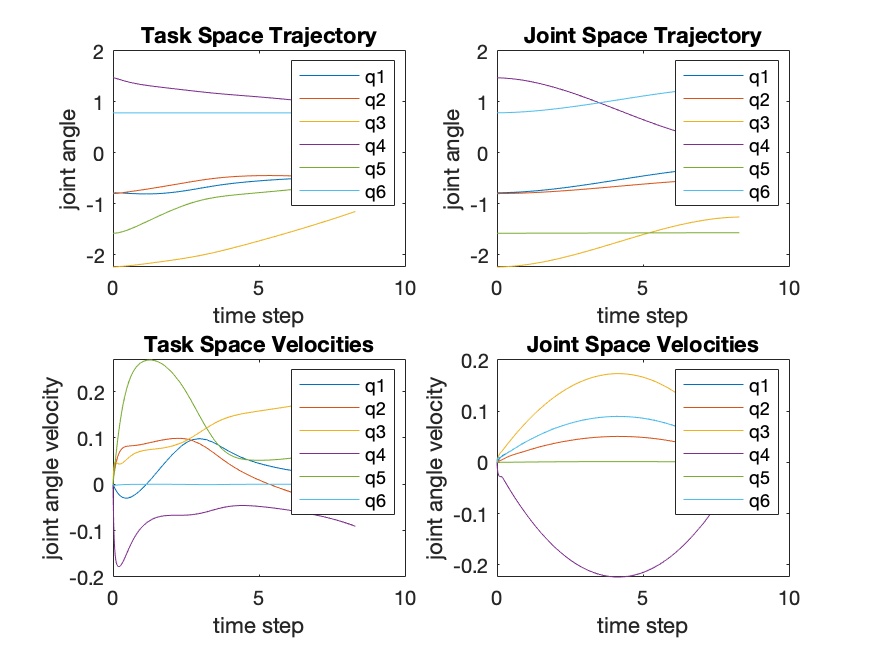

figure()
subplot(2,2,1)
plot(tTask,stateTask(:,1:6))
title('Task Space Trajectory')
xlabel('time step')
ylabel('joint angle')
legend('q1','q2','q3','q4','q5','q6')
subplot(2,2,2)
plot(tJoint,stateJoint(:,1:6))
title('Joint Space Trajectory')
xlabel('time step')
ylabel('joint angle')
legend('q1','q2','q3','q4','q5','q6')
subplot(2,2,3)
plot(tTask,stateTask(:,7:12))
title('Task Space Velocities')
xlabel('time step')
ylabel('joint angle velocity')
legend('q1','q2','q3','q4','q5','q6')
subplot(2,2,4)
plot(tJoint,stateJoint(:,7:12))
title('Joint Space Velocities')
xlabel('time step')
ylabel('joint angle velocity')
legend('q1','q2','q3','q4','q5','q6')

%% 
% 
% 
% _Version 1: Cormac O'Neill, 2021_